# CBF for Kinematic Control

- Robot: UR3

- Control algorithm: Velocity control

% 2024-06-03
% Reference: A. Singletary, S. Kolathaya, and A. D. Ames, “Safety-Critical Kinematic Control of Robotic Systems,” _IEEE Control Syst. Lett._, vol. 6, pp. 139–144, 2022 논문 공부

clc
clear
close all

## Model parameters and initial conditions

gamma = 1;
lambda = 1;
Tf = 4; % Duration
Ts = 0.001; % Sample time
x_obs = [0 0.45 0.2];
R = 0.15; % Radious of obstacle
R_w = 0.05; % Radious of tool
d = R + R_w;
% d = 0;

## Load and display robot

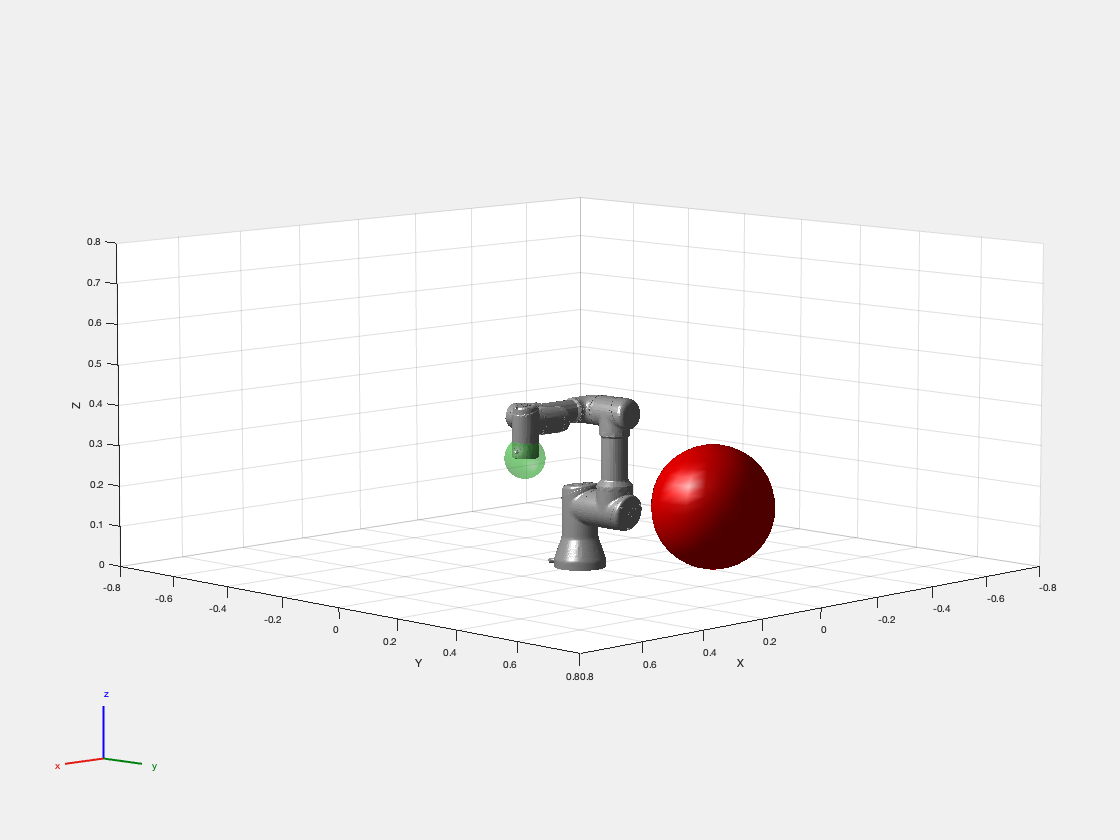

robot = loadrobot('universalUR3', DataFormat="column");
config = homeConfiguration(robot);
config(2) = -pi/2;
config(3) = pi/2; 
config(4) = -pi/2; 
config(5) = -pi/2;

transform = getTransform(robot, config, "tool0");
InitPos = tform2trvec(transform);
InitAng = tform2eul(transform);

%interactiveGUI = interactiveRigidBodyTree(robot);


f = figure(1);
f.Position(3:4) = f.Position(3:4)*2;

axes = show(robot, config, "Frames","off");
axis([-0.8 0.8 -0.8 0.8 0 0.8]);

% Draw obstacle
[X, Y, Z] = sphere(20);
X = R*X + x_obs(1);
Y = R*Y + x_obs(2);
Z = R*Z + x_obs(3);

s = patch(surf2patch(X, Y, Z));
s.FaceColor = 'red'; 
s.FaceLighting = 'gouraud'; %각 면 간에 조명이 달라지게 해서 곡면으로 보임
s.EdgeAlpha = 0; % 테두리가 없음

% Draw safety volume of the wrist
[X, Y, Z] = sphere(20);
X = R_w*X + InitPos(1);
Y = R_w*Y + InitPos(2);
Z = R_w*Z + InitPos(3);

s = patch(surf2patch(X, Y, Z));
s.FaceColor = 'green'; 
s.FaceLighting = 'gouraud'; %각 면 간에 조명이 달라지게 해서 곡면으로 보임
s.FaceAlpha = 0.3;
s.EdgeAlpha = 0; % 테두리가 없음

## Generate Task space trajectory

% finalPoint = [-0.3 0.5 0.4];
% finalPoint = InitPos + [0 -0.3 0];
finalPoint = [-0.2 0.45 0.2];

taskInit = transform;
taskFinal = trvec2tform(finalPoint)*axang2tform(tform2axang(transform));

distance = norm(tform2trvec(taskInit) - tform2trvec(taskFinal));

initTime = 0;
finalTime = Tf;
trajTimes = initTime:Ts:finalTime;
timeInterval = [trajTimes(1); trajTimes(end)];

[taskWaypoints, taskVelocities] = transformtraj(taskInit, taskFinal, timeInterval, trajTimes);
wayPointsVec = tform2trvec(taskWaypoints);
wayPointsAng = tform2eul(taskWaypoints);
wayPointsData = [trajTimes', wayPointsAng, wayPointsVec]; % Add the time for 'From Workspace' block in Simulink
velocityData = [trajTimes', taskVelocities'];
%wayPointsVec = [wayPointsVec(1,:); wayPointsVec]; % Simulink 출력 개수에 맞춰서 보정


## Simulink model

mdl = 'CBF_for_KinematicControl_UR3';
open_system(mdl)

out = sim(mdl);


## Plot trajectories of the tool

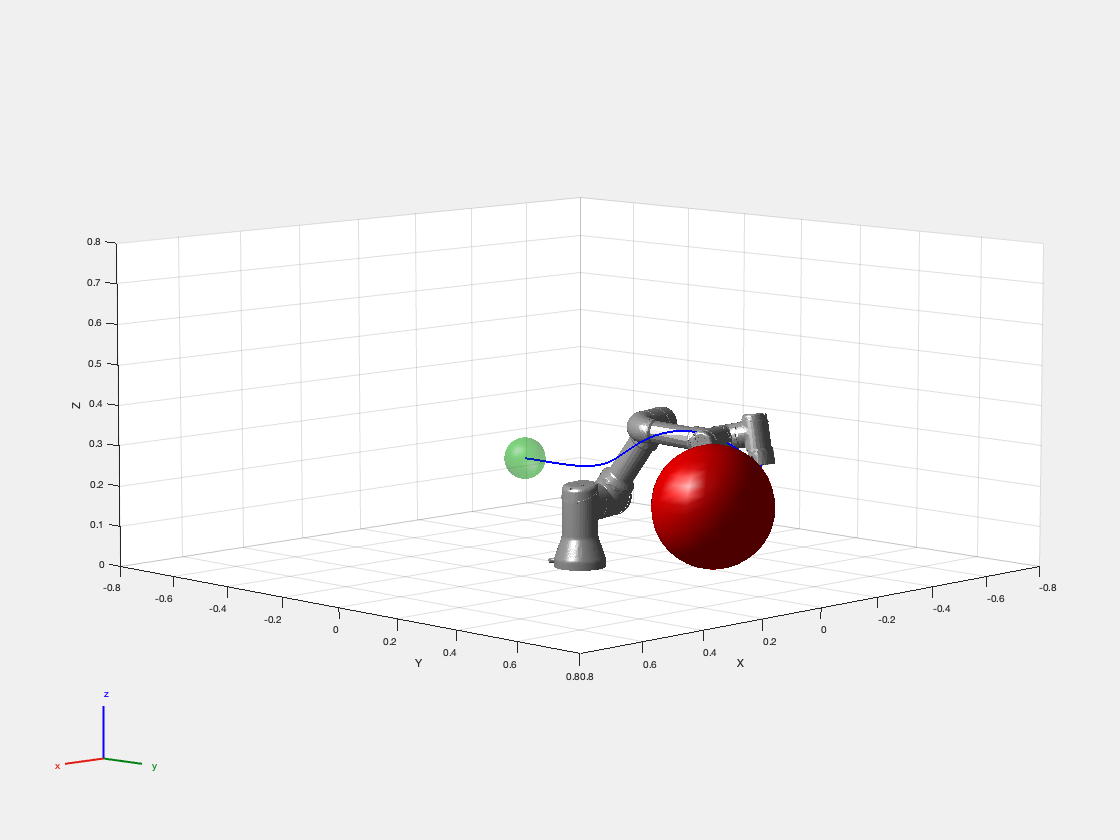

logData = out.logsout;
px = zeros(size(out.tout));
py = zeros(size(out.tout));
pz = zeros(size(out.tout));
hx = zeros(size(out.tout));
u_act  = zeros(size(out.tout, 1), 6);
q = zeros(size(out.tout, 1), 6);

for ct = 1:size(out.tout, 1)
    px(ct) = logData{3}.Values.Data(ct, 4);
    py(ct) = logData{3}.Values.Data(ct, 5);
    pz(ct) = logData{3}.Values.Data(ct, 6);
    hx(ct) = logData{1}.Values.Data(ct);
    q(ct, :) = logData{2}.Values.Data(ct,:);
end

figure(1)
hold on

plot3(px, py, pz, 'LineWidth', 2, 'Color','b');
frameSkip = 10;
for i = 2:frameSkip:size(out.tout, 1)
    show(robot, q(i,:)', 'Frames', 'off', 'PreservePlot',false);
    pause(0.01);
end

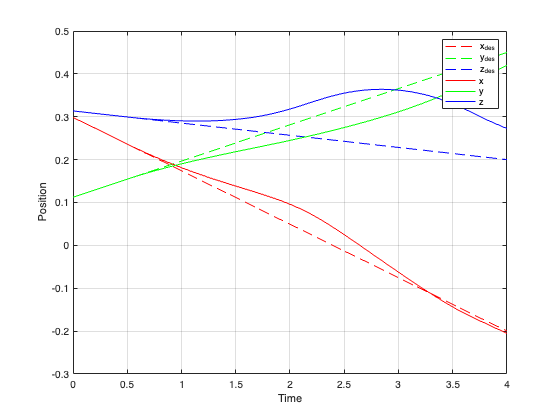


% Plot
figure('Name','Position of the wirst');
plot(out.tout, wayPointsVec(:,1), 'r', out.tout, wayPointsVec(:,2), 'g', out.tout, wayPointsVec(:,3), 'b', 'LineStyle','--');
hold on
plot(out.tout, px, 'r', out.tout, py, 'g', out.tout, pz, 'b'), grid;
xlabel('Time');
ylabel('Position');
legend('x_{des}', 'y_{des}', 'z_{des}', 'x', 'y', 'z');

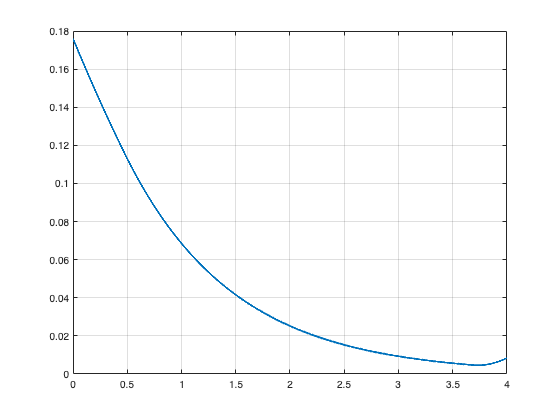


figure('Name','The values of CBF');
plot(out.tout, hx, 'LineWidth', 2);
grid;